# Creación de funciones

Las funciones son una serie de instrucciones que funciones con una o varias entradas (en raros casos con ninguna) y que devuelven una o varias salidas.

Previamente ya hemos estudiado las funciones internas de MATLAB, aquellas que vienen integradas dentro de MATLAB y en la mayoría de casos serán más que suficiente. No obstante, en esos casos donde estas funciones no sean suficiente, entonces deberemos crear nuestras propias funciones.

Estas funciones que podemos crear siguen la misma lógica que las funciones internas de MATLAB, así que aprendemos únicamente la forma de crearlas y en qué se diferencian de un script o live script.

## Palabra reservada `function`

La palabra reservada `function` permite crear funciones de la siguiente forma:

Notemos que se parece bastante a estructuras con las que ya hemos venido trabajando previamente. Veámoslo con un código de ejemplo:

Notemos la función consta de algunas partes, así que vamos a detallarlas paso a paso:

- Escribir la palabra reservada `function` 

- Definir la salida: `c`

- Definir el nombre de la función: `hipotenusa`

- Definir las entradas: `a`, `b`

- Introducir las instrucciones de la función. Para este caso particular es sólo una, pero pueden ser más.

- Devolver la salida calculada.

- Escribir la palabra reservada `end`

Este procedimiento es el mismo para el resto de funciones que podemos encontrar, las cuales son:

- Funciones sin entradas ni salidas

- Funciones con una entrada y una salida

- Funciones con varias entradas y una salida

- Funciones con una entrada y varias salidas

- Funciones con varias entradas y salidas

Ahora que se conocen los diferentes tipos de funciones que dependen de número entradas y salidas, es importante conocer otras características importantes.

## Funciones locales

Las funciones también se pueden clasificar según su ubicación, de las cuales tienen mayor relevancia las funciones locales, de las cuales existen dos tipos:

- Función local dentro del script/live script

- Función local como un archivo de función (function .m o live function .mlx)

Las variables con las que se trabaje dentro de una función local se conocen como variables locales.

### Función local dentro del script/live script

Las funciones locales dentro de los script o live scripts siempre van al final todo el archivo. Siempre.

Si existen más funciones, entonces se deben ir ubicando una debajo de otra, tal que sólo hayan funciones al final, no texto ni código.

Las funciones locales de este tipo sólo pueden ser llamadas dentro del mismo script/live script. Si se requiere llamarla desde otro script/live script, entonces se debe crear la función como un archivo.

### Función local como archivo de función

Las funciones locales como archivo de función deben cumplir un par de de características:

- El nombre del archivo debe tener el mismo nombre que la función creada.

- El archivo de función debe estar en el mismo directorio actual donde se quiera utilizar la función, caso contrario MATLAB no la reconocerá.

## Funciones globales

Como tal, no existen las funciones globales. Sin embargo, se podrían entender como las funciones que creamos y guardamos en una sola carpeta (donde las funciones tienen relación entre sí o sobre un tema en particular), entonces añadimos esta carpeta (que tomaría el nombre de "caja de herramientas" o "toolbox") al directorio de cajas de herramientas de MATLAB.

Entonces MATLAB reconocería las funciones añadidas como funciones internas (por eso se hace mención que no existen como tal las funciones globales) en cualquier script/live script, sin necesidad de que las funciones estén en el mismo directorio actual. Por esto es que se las podría entender como funciones globales, porque se las podría llamar desde cualquier script o live script.

### Palabra reservada `global`

Si bien las funciones globales no existen, las variables globales sí existen. Para declarar variables globales se utiliza la palabra reservada `global`.

Una variable global se puede utilizar dentro del espacio de trabajo base (workspace) y dentro del espacio de trabajo de las funciones. Pero, ¿qué son estos espacios de trabajo?

### Espacios de trabajo

Los espacios de trabajo son una de las más grandes diferencias entre un simple script/live script y una función. 

Es evidente que podemos crear un script que haga cualquier cosa que pensemos y podamos programar, pero una función lo hace más rápido.

El espacio de trabajo base es con el que hemos estado trabajando por defecto. En cuanto creamos una variable, realizamos cálculos, etc., todo esto se guarda en el espacio de trabajo base. No obstante, el espacio de trabajo de funciones se crea cuando se llama a una función, por lo que estará totalmente vacío y únicamente tendrá las entradas que se le dé a la función. Una vez la función termine la serie de instrucciones dentro de ella y devuelva las salidas, el espacio de trabajo de la función se elimina.

**Figura 1.** Información compartida entre scripts/live scripts y funciones.

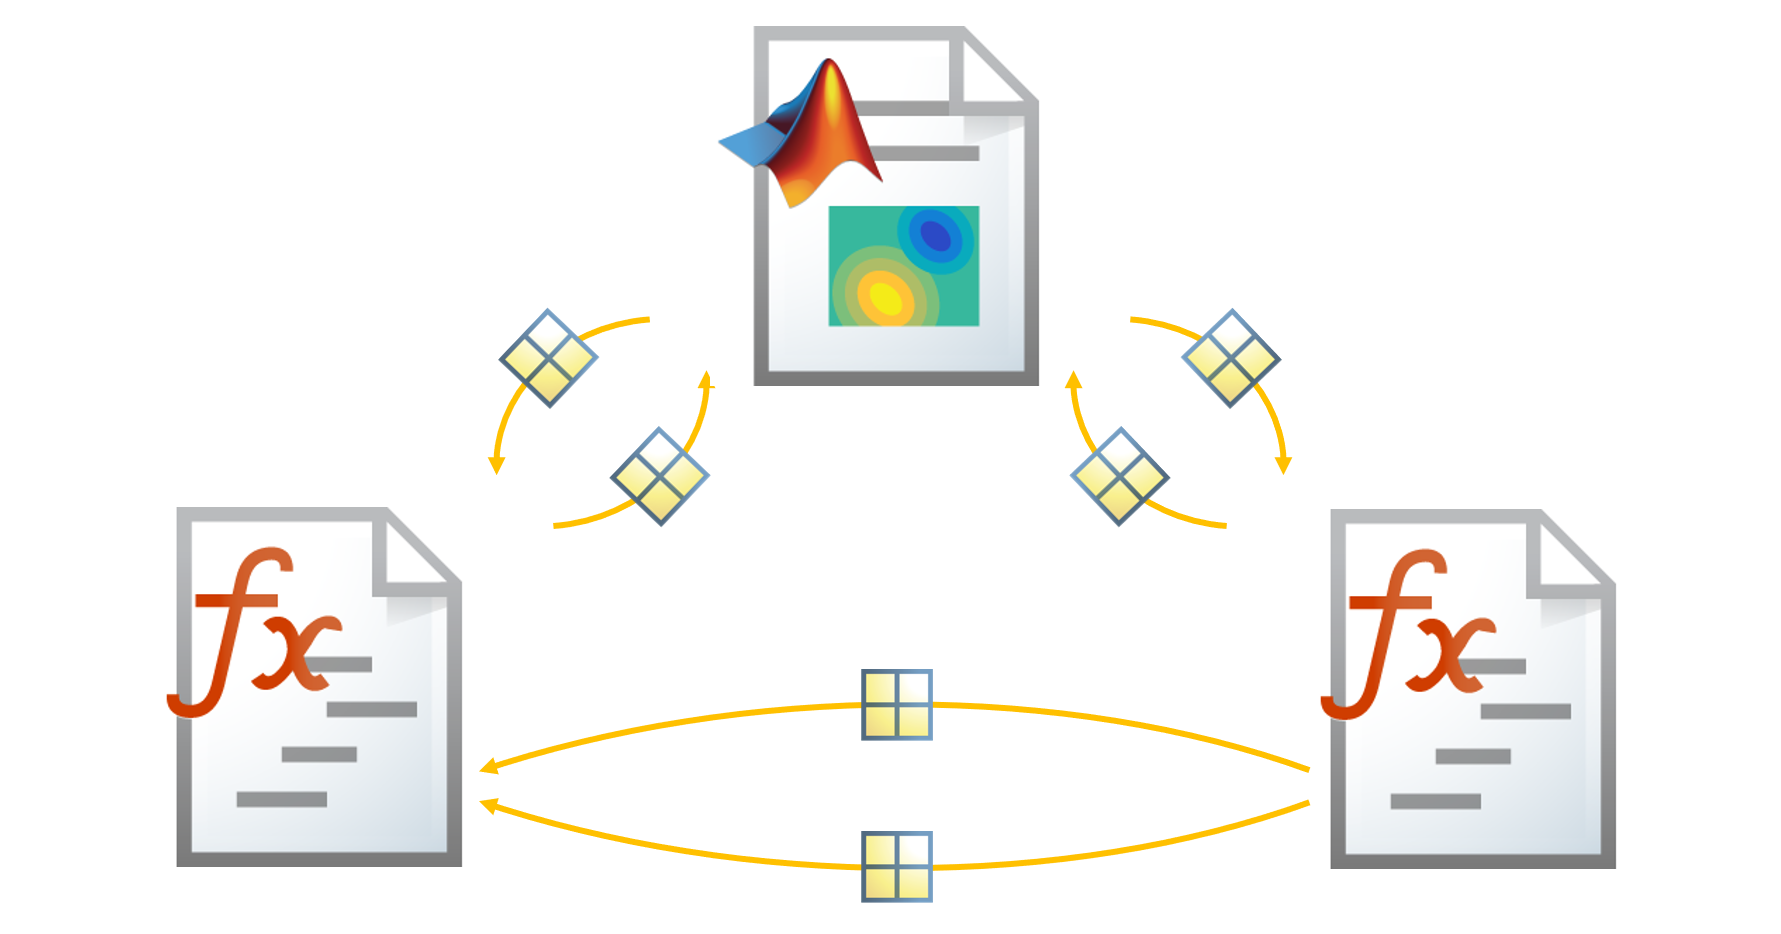

*Tomado de MATLAB Programming Techniques Quick Reference de MathWorks.*

La ventaja de que las funciones tengan su propio espacio de trabajo es que no necesitan espacio (memoria) para guardar variables, funciones, clases o lo que se haya creado previamente. Esto no pasa en el espacio de trabajo base, puesto que debe reservar memoria para todo lo que programemos. He ahí la diferencia y la ventaja de crear funciones frente a utilizar código dentro de un script/live script únicamente.

Cabe destacar que los espacio de trabajo están aislados uno del otro. La única conexión que tienen es cuando se llama a una función, entonces la función crea su espacio de trabajo obteniendo del espacio de trabajo base las entradas y luego devolviendo las salidas.

La única forma de de acceder a ambos espacios de trabajo a la vez es a través de variables globales, las cuales sí son reconocidas en ambos espacios de trabajo. No obstante, no se recomienda su uso dado que dificulta la detección de errores a largo plazo.

Solamente se recomienda su uso a programadores con experiencia y una noción bastante buena del código que están manejando, caso contrario es mejor evitarlas. Más información en el material adicional.

## Añadir documentación a una función

Como vimos, podemos crear funciones manualmente. Sin embargo, MATLAB provee de una opción para crear archivos de función directamente.

**Figura 2.** Diferentes archivos que se pueden crear a través de la pestaña HOME, menú FILE. 

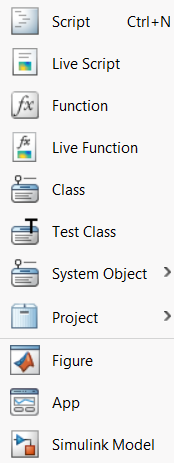

*Tomado del entorno de MATLAB, versión R2022a.*

En la Fig. 1 se puede ver los archivos más comúnes que se pueden crear con MATLAB, entre ellos *Function* y *Live Function*.

Ahora bien, si creamos una Live Fuction utilizando la forma antes descrita, se crear un archivo base con la siguiente estructura. **Aclaración:** Los colores están modificados, pero la estructura es lo importante, la cual no cambia.

**Figura 3.** Estructura base de una Live Function creada a partir de la opción de MATLAB.

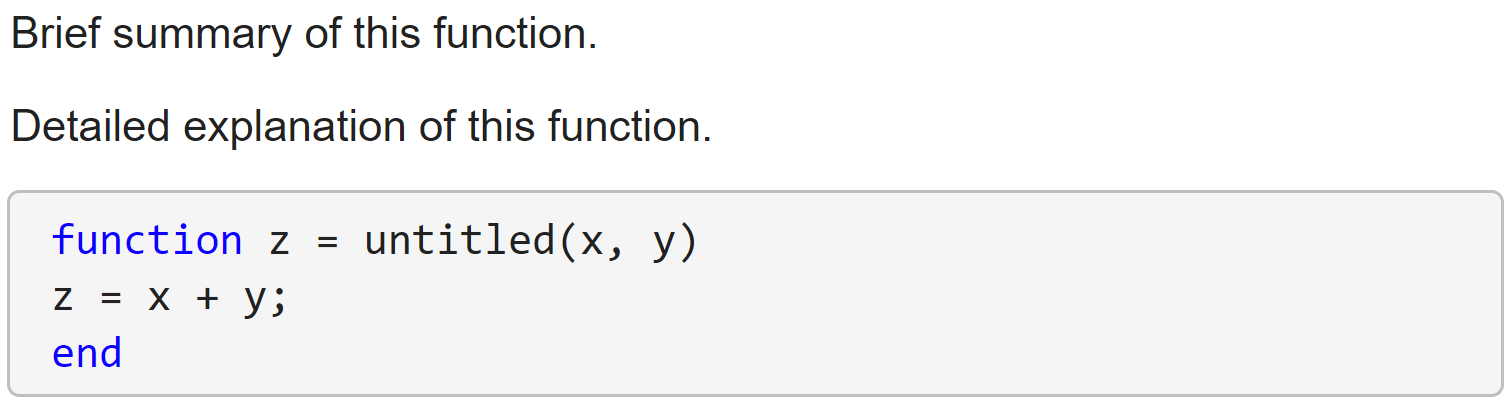

*Tomado del entorno de MATLAB, versión R2022a.*

Como se puede ver en la Fig. 2, es posible añadir un breve resumen de la función y luego una explicación detallada de esta.

Se recomienda seguir el estilo de documentación de MATLAB para la documentación que se desee añadir a las funciones de propia autoría.

Recordemos que la función `help` permite consultar la documentación de MATLAB de una función.

% Ingrese su código aquí :)

Por lo tanto, tomando como base la documentación de cualquier función se recomienda generar nuestra propia documentación. Así pues, cuando se solicite ayuda de nuestra función (utilizando la función `help`) se desplegará tal como lo hayamos indicado.

% Ingrese su código aquí :)

A pesar que los live scripts sean tan versátiles y útiles, las live functions no han tenido el mismo impacto, por lo que se recomienda utilizar functions (archivos .m) en lugar de live functions (archivos .mlx). La diferencia radica en la forma de hacer la documentación. Para la documentación de functions (archivos .m) se puede consultar el material adicional.

**Figura 4.** Estructura base de una Function creada a partir de la opción de MATLAB.

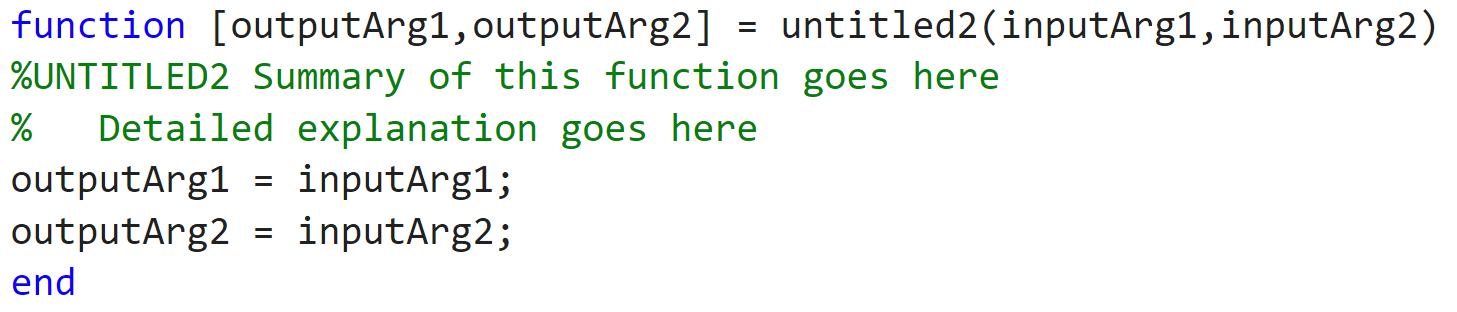

*Tomado del entorno de MATLAB, versión R2022a.*

## Material adicional

- [Funciones](https://www.mathworks.com/help/matlab/functions.html)

- [Creación de funciones](https://www.mathworks.com/help/matlab/function-basics.html)

- [Funciones locales](https://www.mathworks.com/help/matlab/matlab_prog/local-functions.html)

- [Crear funciones en archivos](https://www.mathworks.com/help/matlab/matlab_prog/create-functions-in-files.html)

- [Espacio de trabajo base y espacio de trabajo de funciones](https://www.mathworks.com/help/matlab/matlab_prog/base-and-function-workspaces.html)

- [Añadir documentación a una función](https://www.mathworks.com/help/matlab/matlab_prog/add-help-for-your-program.html)